# **HW5_105060012_Paper Assignment_matlab**

**By: 105060012 張育菘**

1. 

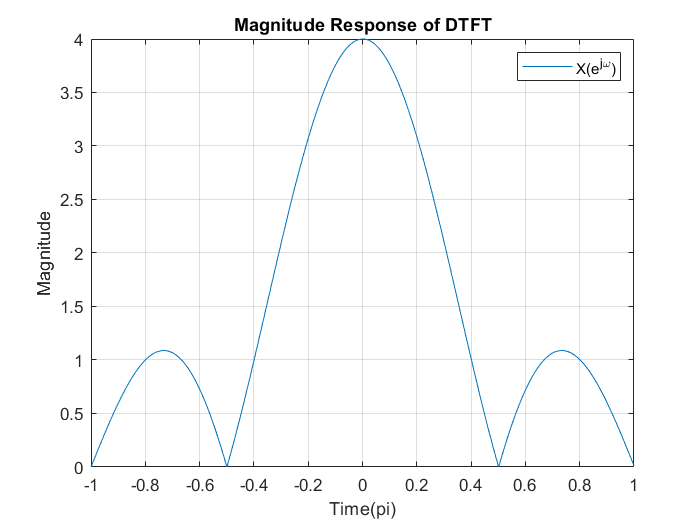

close all; clear;

n = linspace(0, 1023, 1024);
om = linspace(-pi, pi, 1024);

x = zeros(1, 1024);
for i = 1:1:4
    x(i) = 1;
end

X_ft = fft(x); X_ft = fftshift(X_ft);
Amp = 2*cos(om.*0.5) + 2*cos(om.*1.5);
Amp_psi = -1.5.*om;

figure; plot(om/pi, abs(X_ft)); grid on;
title('Magnitude Response of DTFT');
legend('X(e^j^\omega)')
ylabel('Magnitude');
xlabel('Time(pi)');

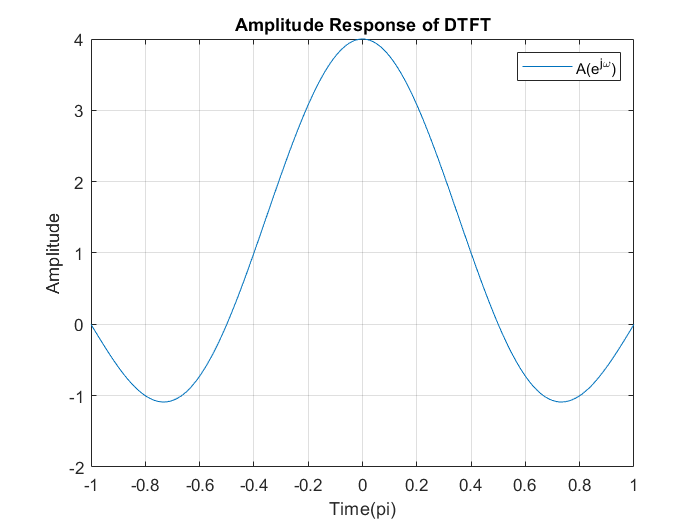


figure; plot(om/pi, Amp); grid on;
title('Amplitude Response of DTFT');
legend('A(e^j^\omega)')
ylabel('Amplitude');
xlabel('Time(pi)');

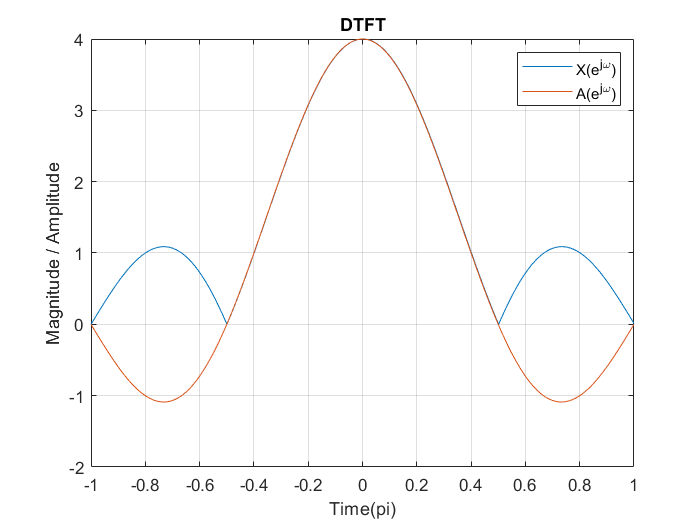


figure; plot(om/pi, abs(X_ft)); hold on; 
plot(om/pi, Amp); hold off; grid on;
title('DTFT');
legend('X(e^j^\omega)', 'A(e^j^\omega)')
ylabel('Magnitude / Amplitude');
xlabel('Time(pi)');

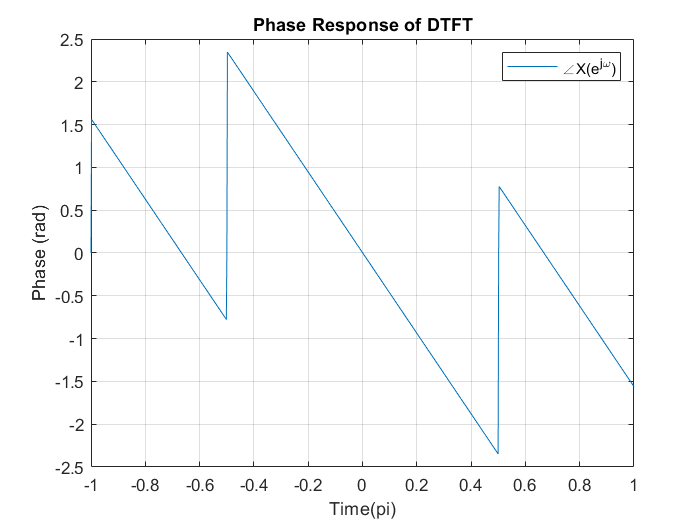


figure; plot(om/pi, angle(X_ft)); grid on;
title('Phase Response of DTFT');
legend('\angleX(e^j^\omega)')
ylabel('Phase (rad)');
xlabel('Time(pi)');

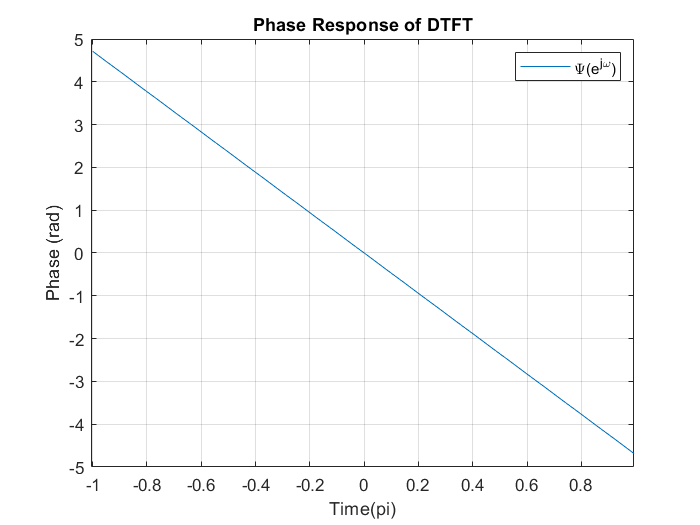


figure; plot(om/pi, Amp_psi); grid on;
title('Phase Response of DTFT');
legend('\Psi(e^j^\omega)')
ylabel('Phase (rad)');
xlabel('Time(pi)');

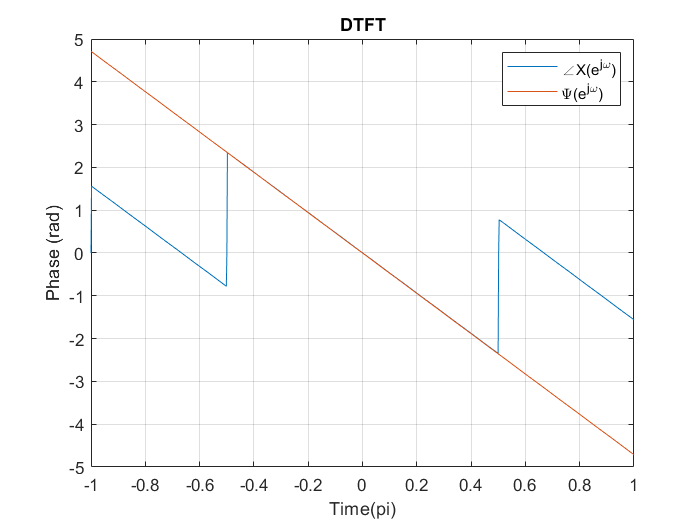


figure; plot(om/pi, unwrap(angle(X_ft))); hold on; 
plot(om/pi, Amp_psi); hold off; grid on;
title('DTFT');
legend('\angleX(e^j^\omega)', '\Psi(e^j^\omega)')
ylabel('Phase (rad)');
xlabel('Time(pi)');